## Workflow example for the DeepInterpolation MATLAB Toolbox

Dr. Thomas Künzel, The MathWorks, 2023

[tkuenzel@mathworks.com](mailto:tkuenzel@mathworks.com?subject=Question%20about%20DeepInterpolation%20MATLAB%20Workflow%20Example)

Please also see the [github repository of the original python-version of DeepInterpolation](https://github.com/AllenInstitute/deepinterpolation) for further information on DeepInterpolation.

## Run setup for initialization of path

base_folder = setup;

#### Set-up options struct

This generates the options struct

deepIntOpts.networkPath = fullfile(base_folder, "sample_data");
deepIntOpts.networkName = "pretrainedNetwork.mat";
deepIntOpts.dataPath = fullfile(base_folder, "sample_data");
deepIntOpts.dataName = "ophys_tiny_761605196.tif";
deepIntOpts.autoResize = false;
deepIntOpts.maxEpochs = 3;
deepIntOpts.miniBatchSize = 3;
deepIntOpts.stepsPerEpoch = 10;
deepIntOpts.initialLearnRate = 0.0001;
deepIntOpts.Verbose = true;
deepIntOpts.Plots = "none";
deepIntOpts.ExecutionEnvironment = "auto";
deepIntOpts.Shuffle = "never"; %set this to at least "once" for GPU or parallel training

#### Initialize datastore object

From the options struct, create the custom datastore object.

dataFullPath = fullfile(deepIntOpts.dataPath, deepIntOpts.dataName);
dids = DeepInterpolationDataStore(dataFullPath, deepIntOpts.autoResize);

#### Set training options

tempLoad = load(fullfile(deepIntOpts.networkPath,deepIntOpts.networkName));
pretrainednet = tempLoad.output;

options = trainingOptions('rmsprop', ...
    'MaxEpochs',deepIntOpts.maxEpochs,...
    'MiniBatchSize',deepIntOpts.miniBatchSize, ...
    'InitialLearnRate',deepIntOpts.initialLearnRate, ...
    'ValidationFrequency',deepIntOpts.stepsPerEpoch,...
    'Verbose',deepIntOpts.Verbose,...
    'Plots',deepIntOpts.Plots,...
    'Shuffle',deepIntOpts.Shuffle,...
    'ExecutionEnvironment',deepIntOpts.ExecutionEnvironment);

#### Train network

Train the network, using the datastore as data source.

output = trainNetwork(dids, pretrainednet.layerGraph, options);

Training on single CPU.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:05 |     45694.84 |      1.0e+09 |      1.0000e-04 |
|       3 |          36 |       00:02:24 |     45962.60 |      1.1e+09 |      1.0000e-04 |
|========================================================================================|
Training finished: Max epochs completed.


save the retrained network

retrainedNetFilename = fullfile("retrainedNetwork_" + datestr(now,'YYYYmmDD_HHMMSS') + ".mat");
save(fullfile(deepIntOpts.networkPath,retrainedNetFilename),'output');

#### Inference: Denoise Stack on local machine

%Setup Path- and Filenames
deepIntOpts.networkName = "retrainedNetwork_20230305_195921.mat"; %modify if you want to use the retrained network (not necessary for demo)

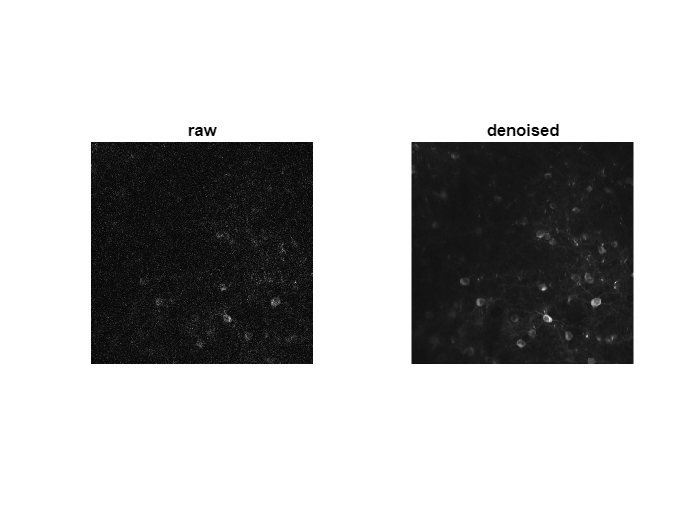

%denoise one frame (for debug)
nFrame = 50;
deepIntInference(deepIntOpts, nFrame);

%denoise all frames
deepIntInference(deepIntOpts);

#### Show Result

This loads the original and denoised tiff stacks and displays them side-by-side. Use the slider after the for-loop completed to view the videos.

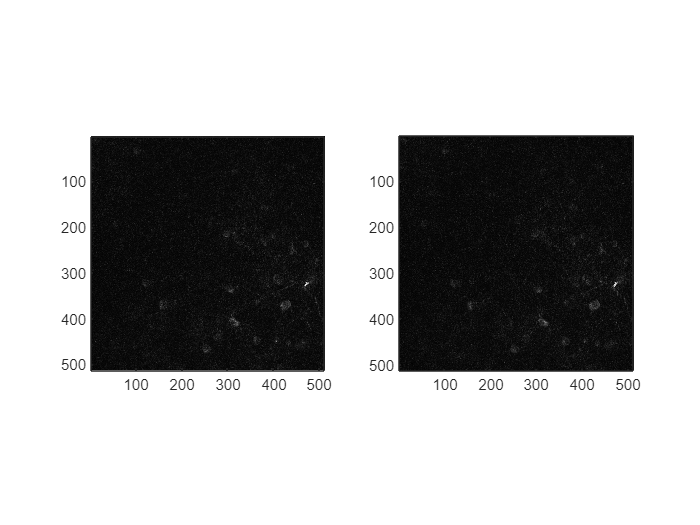

%load data
fileNameDenoised = "denoised_ophys_tiny_761605196.tif";
ori = tiffreadVolume(fullfile(deepIntOpts.dataPath, deepIntOpts.dataName));
di = tiffreadVolume(fullfile(deepIntOpts.dataPath, fileNameDenoised));
dataDimensions = size(ori);

%show denoised frames
for iframe = 1:dataDimensions(3)
    subplot(1,2,1)
    imagesc(ori(:,:,iframe));
    axis image
    subplot(1,2,2)
    imagesc(di(:,:,iframe));
    axis image
    colormap gray
    drawnow
end